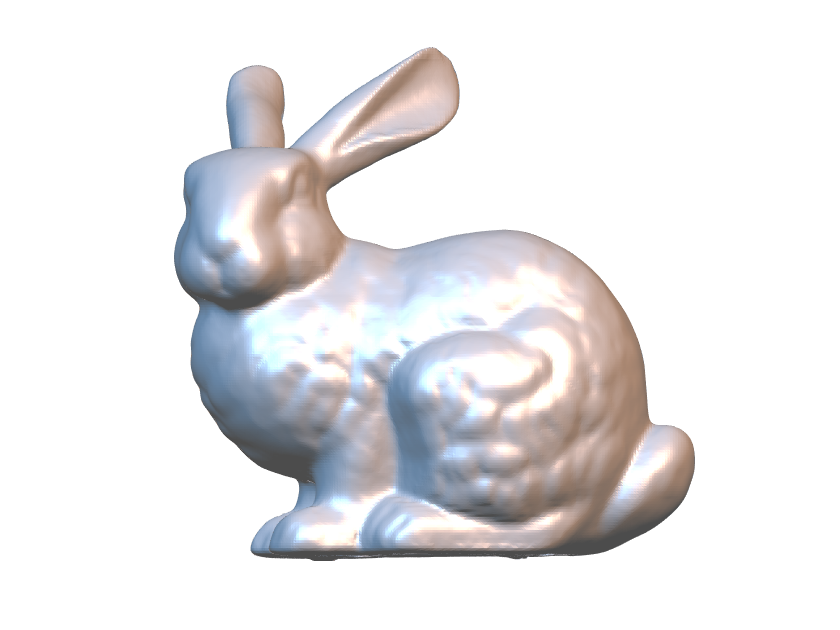

res = 200;
%bunny
minPoint = [-0.0946 0.0333 -0.0618];
maxPoint = [0.0610 0.1873 0.0588];
%dragon
% minPoint = [-0.090 0.052 -0.052];
% maxPoint = [0.098 0.199 0.043];
%buddha
% minPoint=[-0.0461 0.0498 -0.0474];
% maxPoint=[0.0352 0.2478 0.0340];
%Bimba
% minPoint=[-8.663986 -10.000000 -7.216264];
% maxPoint=[8.663986 10.000000 7.216264];
%Torus
%  minPoint=[-0.588880 -0.588886 -0.091571];
%  maxPoint=[0.588464 0.588887 0.091574];
%MaxPlanck_10
% minPoint=[-5.907623 -9.872915 -7.504540];
% maxPoint=[5.888952 9.996798 7.475170];
%cow
% minPoint=[-0.657 -0.591 -0.286];
% maxPoint=[0.975 0.472 0.286];
%dog
% minPoint=[-0.757 -1.000 -0.855];
% maxPoint=[0.757 1.000 0.855];
%teddy
% minPoint=[-0.658921 -0.716940 -0.360366];
% maxPoint=[0.650144 0.941371 0.570984];
xlim = [minPoint(1) maxPoint(1)];
x = xlim(1):(xlim(2)-xlim(1))/res:xlim(2);
ylim = [minPoint(2) maxPoint(2)];
y = ylim(1):(ylim(2)-ylim(1))/res:ylim(2);
zlim = [minPoint(3) maxPoint(3)];
z = zlim(1):(zlim(2)-zlim(1))/res:zlim(2);
[MX,MY,MZ] = meshgrid(x,y,z);
V = reshape(V,res+1,res+1,res+1);
h = figure;
ax = axes('Parent',h);
ax.YAxis.Visible = 'off';
ax.XAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
p = patch(isosurface(MX,MY,MZ,V,0));
isonormals(MX,MY,MZ,V,p);
view(2);
% p.FaceColor = [0.9 0.9 0.8];
p.FaceColor = 'white';
p.EdgeColor = 'none';
daspect([1 1 1]);
axis tight
leftlgt = camlight('left');
leftlgt.Color = [60 128 200]/255;
% leftlgt.Color = [20 60 255]/255;
rightlgt = camlight('right');
rightlgt.Color = [200 126 80]/255;
%rightlgt.Color = [180 120 80]/255;
material default;
hold on;
%ptCloud.Intensity = ApproxArgs;
%pcshow(ptCloud);
% view(2)
% axis normal;
  hold off;

%ptCloud = pcread('bunny_453.ply');

%figure;
%pcshow(ptCloud);